% first generate some data 
% NOTE: this can take a while -- should run for approx 10^6 timesteps to
% get a number of UP/DOWN states comparable to the data


simtime = 30000;

dt = 1;

parms.N_neurons = 4;
parms.I_in = [3.35, 2.72, 3.36, 2.77]';
parms.W = [3.04,-1.5,0,0; 3.24,-0.5,0,0; 0,0,2.83,-1.5; 0,0,3.03,-0.5];
parms.LR = [0.13793;0.724137;0.103448;0.068955];
parms.beta = [-0.8;0.8];
parms.tau_r = [1;1;1;1];
parms.tau_a = [100;100;120;120];


parms.A0 = [2;2];
parms.Ak = [-20;20];


parms.k = [0.02;0.05;0.02;0.05];
parms.h = [0;12;0;12];
parms.n = 2;

parms.noiseamp =0.37;
parms.noisefreq = 0.05;

Y_sol = SSAdapt_run_delay(simtime,dt,parms);

%save(sprintf('%d.mat',id),'Y_sol','parms')

## FIGURE 8B

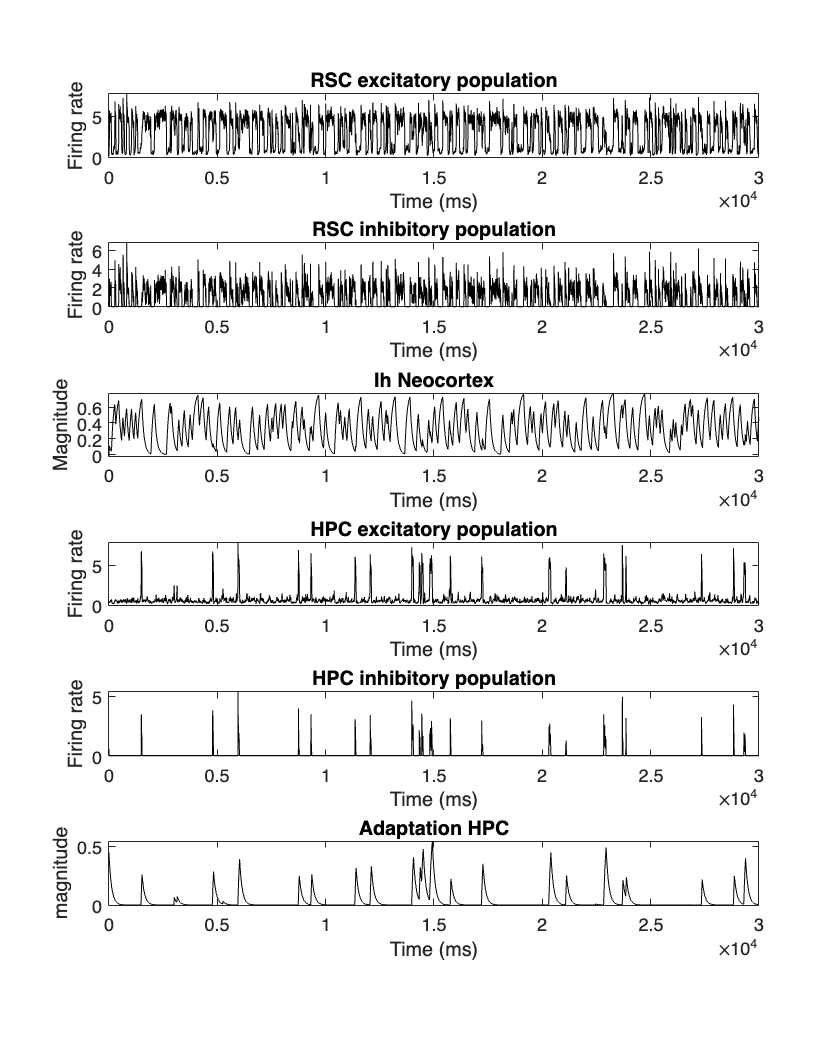


% plot the raw traces
figure;
set(gcf, 'Position', [100 100 800 1000])
subplot(6,1,1)
        plot(Y_sol.x,Y_sol.y(1,:),'k')
        %ylim([0 6.1])
        title("RSC excitatory population")
        xlabel('Time (ms)')
        ylabel('Firing rate')
subplot(6,1,2)
        plot(Y_sol.x,Y_sol.y(2,:),'k')

        %ylim([0 6.1])
        title("RSC inhibitory population")
        xlabel('Time (ms)')
        ylabel('Firing rate')
subplot(6,1,3)
        plot(Y_sol.x,-Y_sol.y(5,:),'k')
        title("Ih Neocortex")
        xlabel('Time (ms)')
        ylabel('Magnitude')
subplot(6,1,4)
        plot(Y_sol.x,Y_sol.y(3,:),'k')

        ylim([0 max(Y_sol.y(3,:))])
        title("HPC excitatory population")
        xlabel('Time (ms)')
        ylabel('Firing rate')
subplot(6,1,5)
        plot(Y_sol.x,Y_sol.y(4,:),'k')

        ylim([0 max(Y_sol.y(4,:))])
        title("HPC inhibitory population")
        xlabel('Time (ms)')
        ylabel('Firing rate')
subplot(6,1,6)
        plot(Y_sol.x,Y_sol.y(7,:),'k')

        %ylim([0 1])
        title("Adaptation HPC")
        xlabel('Time (ms)')
        ylabel('magnitude')

## FIGURE 8D

% calculate average firing rates of HPC and RSC relative to RSC UP and
% preceding DOWN states
% also calculates P(SWR)

[hpc, rsc, p_swr,down_start_time,up_start_time,SWR_indices] = mua_calculator(Y_sol);  

Schmidt


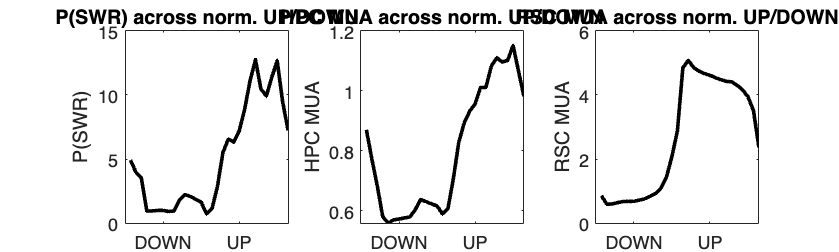


figure;
set(gcf, 'Position', [100 100 1000 300])
subplot(1,3,1)
    plot(p_swr','DisplayName','global','Color','black','LineWidth',2);
    ylabel('P(SWR)')
    xticks([14/2 14*3/2])
    xticklabels({"DOWN","UP"})
    set(gca, 'FontSize', 10);
    title("P(SWR) across norm. UP/DOWN")
subplot(1,3,2)
    plot(mean(hpc,1)','DisplayName','global','Color','black','LineWidth',2);
    ylabel('HPC MUA')
    xticks([14/2 14*3/2])
    xticklabels({"DOWN","UP"})
    %ylim([0 1])
    set(gca, 'FontSize', 10);
    title("HPC MUA across norm. UP/DOWN")
subplot(1,3,3)
    plot(mean(rsc,1)','DisplayName','global','Color','black','LineWidth',2);
    ylabel('RSC MUA')
    xticks([14/2 14*3/2])
    xticklabels({"DOWN","UP"})
    %ylim([0 1])
    set(gca, 'FontSize', 10);
    title("RSC MUA across norm. UP/DOWN")

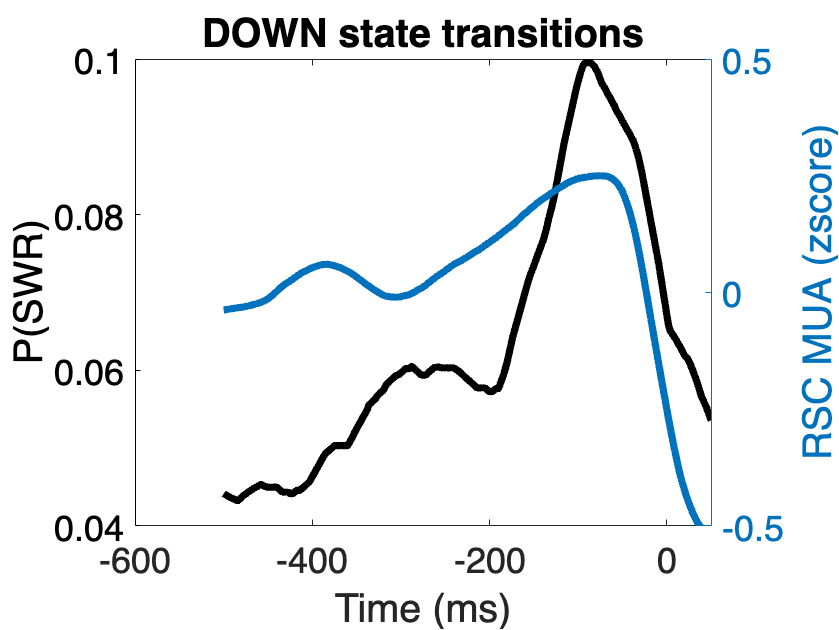

% First plot: Before DOWN state
window_before_down = 500;
window_after_down = 50;

% Initialize matrices for DOWN transitions
raster_matrix_down = zeros(length(down_start_time), window_before_down + window_after_down + 1);
raster_ups_down = zeros(length(down_start_time), window_before_down + window_after_down + 1);

% Get and normalize firing rates
firing_rates_all = Y_sol.y(1,:);  % RSC firing rates
mean_rate = mean(firing_rates_all);
max_deviation = max(abs(firing_rates_all - mean_rate));

% Fill matrices for DOWN state transitions
for i = 1:length(down_start_time)
    window_start = down_start_time(i) - window_before_down;
    window_end = down_start_time(i) + window_after_down;
    
    if window_start >= 1 && window_end <= length(Y_sol.y)
        window_indices = window_start:window_end;
        
        % Get SWR indices
        raster_matrix_down(i, :) = ismember(window_indices, SWR_indices);
        
        % Get and normalize firing rates
        firing_rates = Y_sol.y( 1,window_indices);
        normalized_rates = (firing_rates - mean_rate) / max_deviation;
        raster_ups_down(i, :) = normalized_rates;
    end
end

% Plot DOWN transitions
figure;
x_dots_down = linspace(-window_before_down, window_after_down, window_before_down + window_after_down + 1);

yyaxis left;

plot(x_dots_down, smoothdata(mean(raster_matrix_down, 1)), 'Color', 'black', 'LineWidth', 4);
ylabel('P(SWR)', 'Color', 'black');
set(gca, 'YColor', 'black');

yyaxis right;
plot(x_dots_down, smoothdata(mean(raster_ups_down, 1)), 'Color', [0 0.4470 0.7410], 'LineWidth', 4);
ylabel('RSC MUA (zscore)', 'Color', [0 0.4470 0.7410]);
ylim([-0.5 0.5]);
set(gca, 'FontSize', 20, 'YColor', [0 0.4470 0.7410]);

xlabel('Time (ms)');
title('DOWN state transitions');

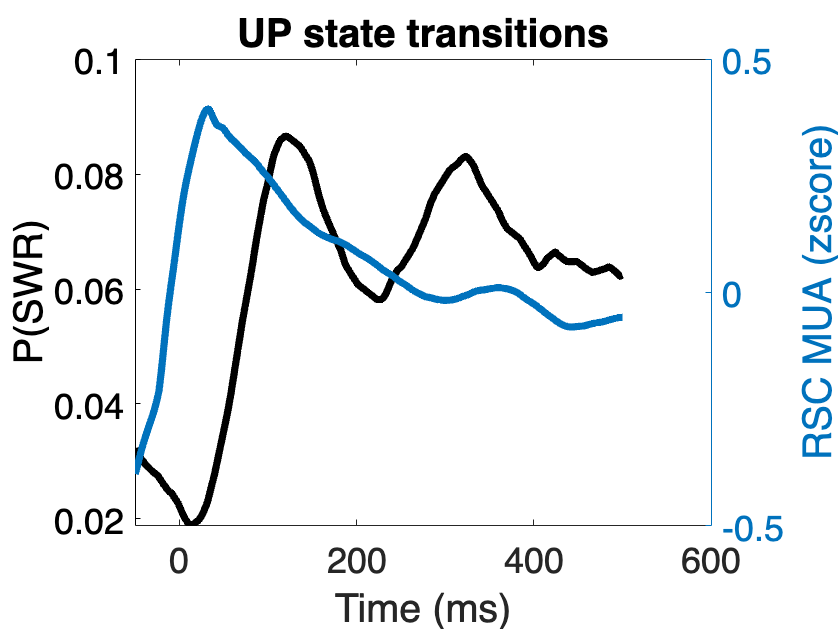


% Second plot: After UP state
window_before_up = 50;
window_after_up = 500;

% Initialize matrices for UP transitions
raster_matrix_up = zeros(length(up_start_time), window_before_up + window_after_up + 1);
raster_ups_up = zeros(length(up_start_time), window_before_up + window_after_up + 1);

% Fill matrices for UP state transitions
for i = 1:length(up_start_time)
    window_start = up_start_time(i) - window_before_up;
    window_end = up_start_time(i) + window_after_up;
    
    if window_start >= 1 && window_end <= length(Y_sol.y)
        window_indices = window_start:window_end;
        
        % Get SWR indices
        raster_matrix_up(i, :) = ismember(window_indices, SWR_indices);
        
        % Get and normalize firing rates
        firing_rates = Y_sol.y(1,window_indices);
        normalized_rates = (firing_rates - mean_rate) / max_deviation;
        raster_ups_up(i, :) = normalized_rates;
    end
end

% Plot UP transitions
figure;
x_dots_up = linspace(-window_before_up, window_after_up, window_before_up + window_after_up + 1);

yyaxis left;
plot(x_dots_up, smoothdata(mean(raster_matrix_up, 1)), 'Color', 'black', 'LineWidth', 4);
ylabel('P(SWR)', 'Color', 'black');
set(gca, 'YColor', 'black');

yyaxis right;
plot(x_dots_up, smoothdata(mean(raster_ups_up, 1)), 'Color', [0 0.4470 0.7410], 'LineWidth', 4);
ylabel('RSC MUA (zscore)', 'Color', [0 0.4470 0.7410]);
ylim([-0.5 0.5]);
set(gca, 'FontSize', 20, 'YColor', [0 0.4470 0.7410]);

xlabel('Time (ms)');
title('UP state transitions');